To derive the state-space equations for the discrete-time version of the dynamics of this system, let's consider the continuous-time equations of motion first:

*m*⋅*x*′′(*t*)=*f*(*t*)

Given that *m*=1 (unit mass), and integrating once to get the velocity, we have:

*x*′(*t*)=∫*f*(*t*)*d**t*

Since *f*(*t*)=*p_n*� is constant over each interval (*n*−1,*n*], the integral becomes:

*x*′(*t*)=∫*n*−1*n*�*p**n*�*d**t*=*p**n*�

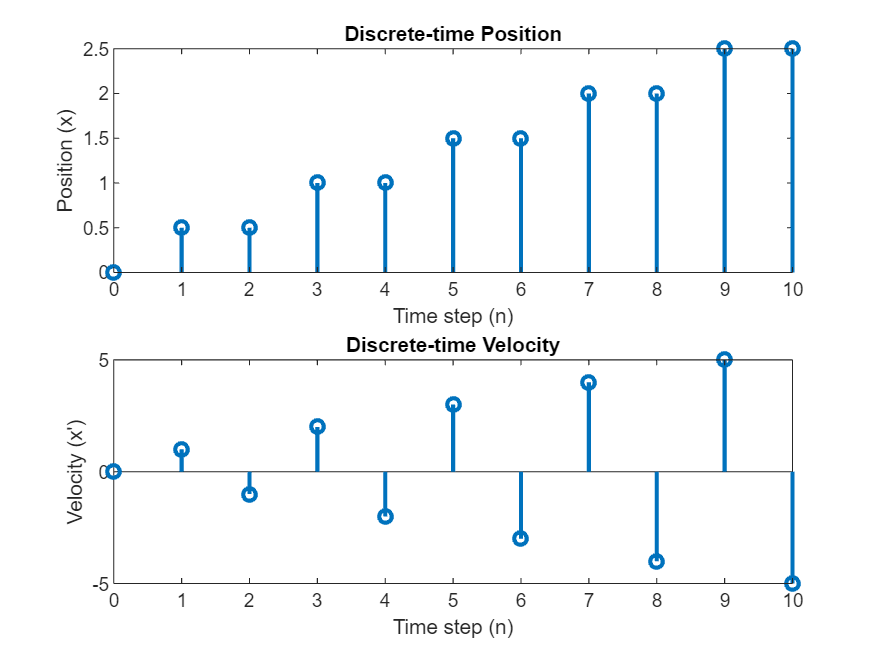

% Define the system matrices
A = [1 1; 0 1];
B = [1/2; 1];

% Number of time steps
N = 10;

% Initialize state vectors
x = zeros(2, N+1);  % x(:, n) represents [x(n); x'(n)]
x(:, 1) = [0; 0];   % Initial conditions

% Define the force vector (piecewise constant)
p = [1, -2, 3, -4, 5, -6, 7, -8, 9, -10];

% Time loop
for n = 2:N+1
    x(:, n) = A * x(:, n-1) + B * p(n-1);
end

% Extract position and velocity vectors
position = x(1, :);
velocity = x(2, :);

% Plot results
figure;

subplot(2, 1, 1);
stem(0:N, position, 'LineWidth', 2);
xlabel('Time step (n)');
ylabel('Position (x)');
title('Discrete-time Position');

subplot(2, 1, 2);
stem(0:N, velocity, 'LineWidth', 2);
xlabel('Time step (n)');
ylabel('Velocity (x'')');
title('Discrete-time Velocity');

% Define the objective function (sum of squares of p_n)
objective = @(p) sum(p.^2);

% Define the linear equality constraints (to satisfy x(10) = 1 and x'(10) = 0)
Aeq = zeros(2, 10);
Aeq(1, 10) = 1;  % x(10) = 1
Aeq(2, 10) = 0;  % x'(10) = 0

beq = [1; 0];   % Values to satisfy the constraints

% Define the lower and upper bounds for p_n
lb = -10*ones(10, 1);
ub = 10*ones(10, 1);

% Initial guess for p_n
x0 = zeros(10, 1);

% Solve the optimization problem
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'interior-point');
p_optimal = fmincon(objective, x0, [], [], Aeq, beq, lb, ub, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      11    0.000000e+00    1.000e+00    1.476e-08
    1      23    2.500000e-01    5.000e-01    5.025e-01    5.000e-01
    2      34    1.000000e+00    1.499e-08    1.369e-02    5.000e-01
    3      45    1.000000e+00    6.544e-11    1.111e-04    4.018e-07
    4      56    1.000000e+00    2.001e-13    1.111e-06    2.208e-07

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the 

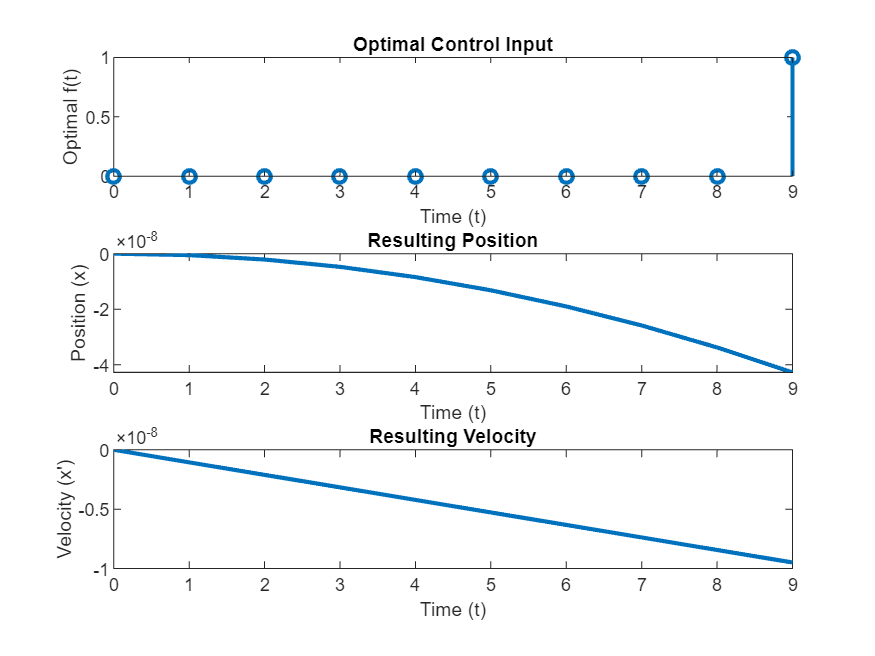


% Generate time vector
t = 0:1:9;

% Simulate the system with the optimal p_n values
x_optimal = simulateSystem(p_optimal);

% Plot the results
figure;

subplot(3, 1, 1);
stem(t, p_optimal, 'LineWidth', 2);
xlabel('Time (t)');
ylabel('Optimal f(t)');
title('Optimal Control Input');

subplot(3, 1, 2);
plot(t, x_optimal(1, :), 'LineWidth', 2);
xlabel('Time (t)');
ylabel('Position (x)');
title('Resulting Position');

subplot(3, 1, 3);
plot(t, x_optimal(2, :), 'LineWidth', 2);
xlabel('Time (t)');
ylabel('Velocity (x'')');
title('Resulting Velocity');

% Objective function (sum of squares)
objective = @(p) sum(p.^2);

% Constraints
nonlinear_constraint = @(p) x_constraint(p);

% Initial guess for p_n
x0 = zeros(10, 1);

% Solve the optimization problem
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'interior-point');
p_optimal = fmincon(objective, x0, [], [], [], [], [], [], nonlinear_constraint, options);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Error in HW4_Application>x_constraint (line 128)
    ceq = A * p - [1; 0];

Error in HW4_Application>@(p)x_constraint(p) (


% Generate time vector
t = 0:0.1:10;

% Simulate the system with the optimal p_n values
x_optimal = simulateSystem(p_optimal);

% Plot the results
figure;

subplot(3, 1, 1);
stem(t, p_optimal, 'LineWidth', 2);
xlabel('Time (t)');
ylabel('Optimal f(t)');
title('Optimal Control Input');

subplot(3, 1, 2);
plot(t, x_optimal(1, :), 'LineWidth', 2);
xlabel('Time (t)');
ylabel('Position (x)');
title('Resulting Position');

subplot(3, 1, 3);
plot(t, x_optimal(2, :), 'LineWidth', 2);
xlabel('Time (t)');
ylabel('Velocity (x'')');
title('Resulting Velocity');


function [c, ceq] = x_constraint(p)
    % Constraint function for x(10) = 1 and x(5) = 0
    A = [1 0; 0 0];
    ceq = A * p - [1; 0];
    c = [];
end

function x = simulateSystem(p)
    % Simulate the system with given p_n values
    A = [1 1; 0 1];
    B = [1/2; 1];
    N = 100;  % Number of time steps
    x = zeros(2, N+1);
    for n = 2:N+1
        x(:, n) = A * x(:, n-1) + B * p(n-1);
    end
end